# Cleaned-Up Square Conducting Analysis

Anil and Samyoung

[square_accel, square_gyro] = parsePowerSenseData_1('anil_perfect_square.csv');

% data grabbing
times = square_accel(:,1);                % grab times column
times = times-times(1);                   % center unex times
x_accel_square = square_accel(1:end,2);   % grab xaccel
z_accel_square = square_accel(1:end,4);   % grab yaccel

num = 8;
h = ones(1, num)./num;    % define convolution shape

% double moving average on z data
zacc = conv(z_accel_square, h);
zacc = zacc(1:end-length(h)+1);
zacc = conv(zacc, h);
zacc = zacc(1:end-length(h)+1);
untouchedz = zacc;

% double moving average on x data
xacc = conv(x_accel_square, h);
xacc = xacc(1:end-length(h)+1);
xacc = conv(xacc, h);
xacc = xacc(1:end-length(h)+1);

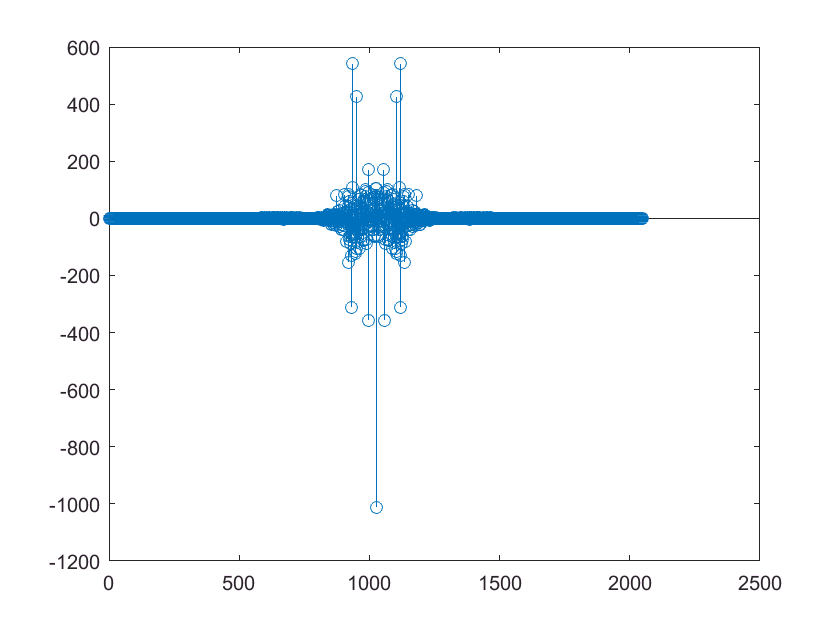

% ideal low pass filter on x data
n = -420:420;      % n parameter
wc = pi/20;        % filter frequency in rad/sec

h = wc/pi * sinc(wc*n/pi);        % define convolution shape
x_ideal = conv(xacc, h);          % convolve xacc with shape
stem(real(fftshift(fft(xacc))))   % check fft of original x

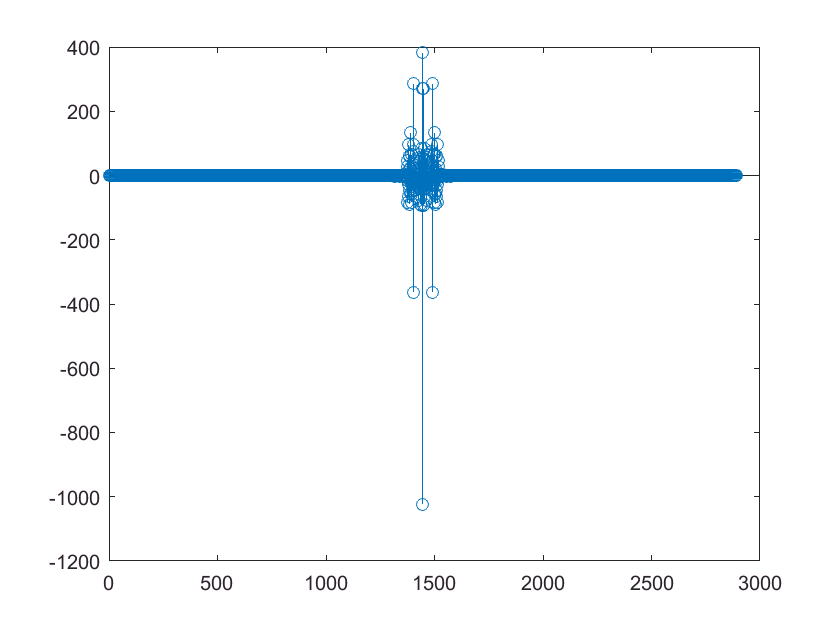

stem(real(fftshift(fft(x_ideal))))% check fft of filtered x

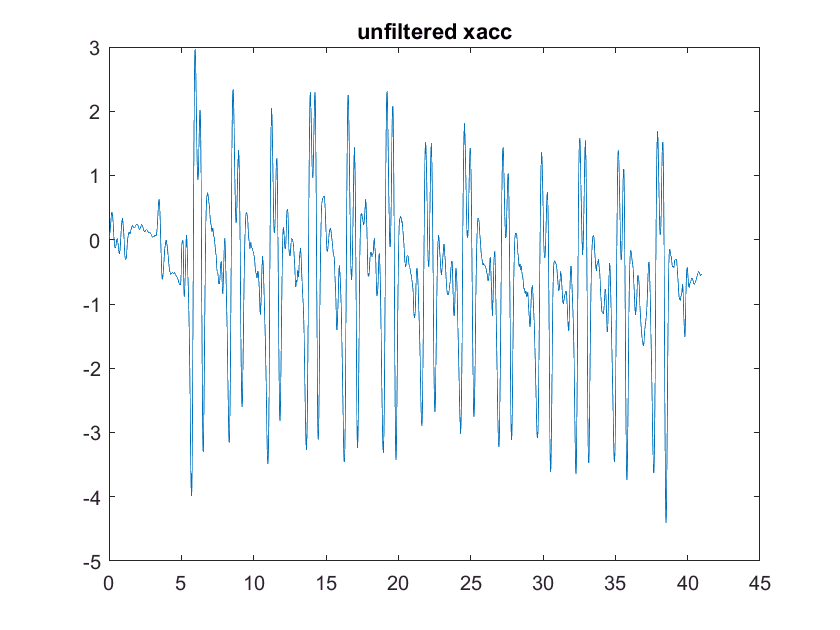


% fix convolution additions
error = (length(x_ideal)-length(xacc))/2;
x_ideal = x_ideal(error+1:end-error);

plot(times, xacc)       % plot the original xacc data
title('unfiltered xacc')

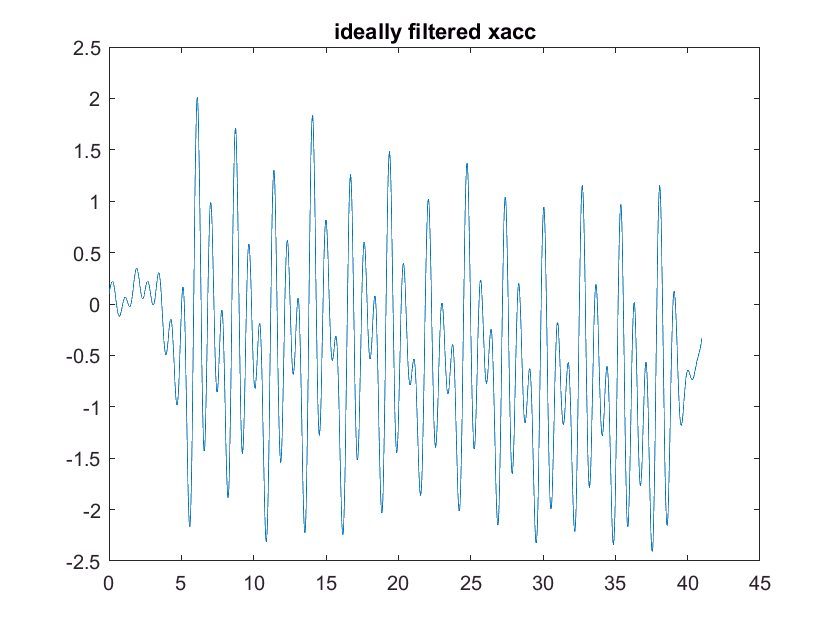

plot(times, x_ideal)    % plot the ideally filtered data
title('ideally filtered xacc')

% z acceleration beat analysis
% beat de-fuzzing
for i = 1 : size(zacc)-4
    if(abs((zacc(i)- 9.81) < 1) && (abs((zacc(i + 2)- 9.81))< 1))
        zacc(i) = 9.81;
    end
end

% initialize some arrays
beatOne = [];
beatThree = [];

% Loop through all zaccels, find ones and threes
for i = 3 : size(zacc)-4
    % beat one checker
    if((zacc(i)== 9.81) && (zacc(i-1)- 9.81 >0) && (zacc(i+ 1)== 9.81))
        beatOne = cat(1, beatOne, i);
    end
    
    % beat three checker
    if((zacc(i)== 9.81) && (zacc(i+1)- 9.81 >0) && (zacc(i- 1)== 9.81))
         beatThree = cat(1, beatThree, i);
    end
end

% Use xaccel to find beat two
binarySignal = x_ideal>0.8;
leadingEdges2 = find(diff(binarySignal) >= 1);
beatTwo = leadingEdges2;
correc = 0.1;

fours = [];
index = 1;

% use local maximums to find beat 4
[pks, locs] = findpeaks(zacc);

for i = 1:length(pks)
    if pks(i) < 8.1
        fours(index) = locs(i);
        index = index+1;
    end
end

beatFour = fours(3:end);
beatFourTimes = times(beatFour);

% Uses indexes to find timestamps
beatOne = beatOne(1:end-1)

beatOne =          270
         402
         532
         664
         797
         935
        1067
        1201
        1334
        1463


beatOneTimes = times(beatOne)

beatOneTimes =     5.3806
    8.0209
   10.6212
   13.2615
   15.9218
   18.6821
   21.3224
   24.0027
   26.6630
   29.2433



good_times = [1 3:5 7:15];
beatTwo = beatTwo(good_times);
beatTwoTimes = times(beatTwo)+correc

beatTwoTimes =     6.0007
    8.6610
   11.3613
   13.9816
   16.6619
   19.3222
   22.0825
   24.7028
   27.3831
   30.0834



beatThree = beatThree(2:end);
beatThreeTimes = times(beatThree)

beatThreeTimes =     6.8008
    9.4211
   12.0214
   14.6617
   17.4820
   20.0623
   22.7626
   25.4429
   28.0232
   30.7235


zacc_squash = zacc;
zacc = zacc-9.81;

% distance integrations
% beat 1
dist_ints1 = zeros(1, length(beatOne)-1);

for i = 1:length(beatOne)-1
    start_temp = beatFour(i);
    end_temp = beatOne(i+1);
    
    times_temp = times(start_temp:end_temp);
    zacc_temp = zacc(start_temp:end_temp);
   
    velocity = cumtrapz(times_temp, zacc_temp);
    position = trapz(times_temp, velocity);
    dist_ints1(i) = position;    
end

% beat 2
dist_ints2 = zeros(1, length(beatTwo)-1);

for i = 1:length(beatTwo)-1
    start_temp = beatOne(i);
    end_temp = beatTwo(i);
    
    times_temp = times(start_temp:end_temp);
    xacc_temp = xacc(start_temp:end_temp);
        
    velocity = cumtrapz(times_temp, xacc_temp);
    % figure()
    % plot(times_temp, velocity)
    position = trapz(times_temp, velocity);
    
    dist_ints2(i) = position;
end

% beat 3
dist_ints3 = zeros(1, length(beatThree)-1);

for i = 1:length(beatThree)-1
    start_temp = beatTwo(i);
    end_temp = beatThree(i);
    
    times_temp = times(start_temp:end_temp);
    xacc_temp = xacc(start_temp:end_temp);
        
    velocity = cumtrapz(times_temp, xacc_temp);
    % figure
    % plot(times_temp, xacc_temp)
    position = trapz(times_temp, velocity);
    
    dist_ints3(i) = position;
end


% beat 4
dist_ints4 = zeros(1, length(beatThree)-1);

for i = 1:length(beatFour)-1
    start_temp = beatThree(i);
    end_temp = beatFour(i);
    
    times_temp = times(start_temp:end_temp);
    zacc_temp = zacc(start_temp:end_temp);
        
    velocity = cumtrapz(times_temp, zacc_temp);
    % figure
    % plot(times_temp, zacc_temp)
    position = trapz(times_temp, velocity);
    
    dist_ints4(i) = position;
end

% conversion
m2in = 39.3701;
dist1 = dist_ints1.*m2in;
dist2 = dist_ints2.*m2in;
dist3 = dist_ints3.*m2in;
dist4 = dist_ints4.*m2in;

% find beat lengths
onetotwo = beatTwoTimes-beatOneTimes;
twotothree = beatThreeTimes-beatTwoTimes;
threetofour = beatFourTimes-beatThreeTimes;

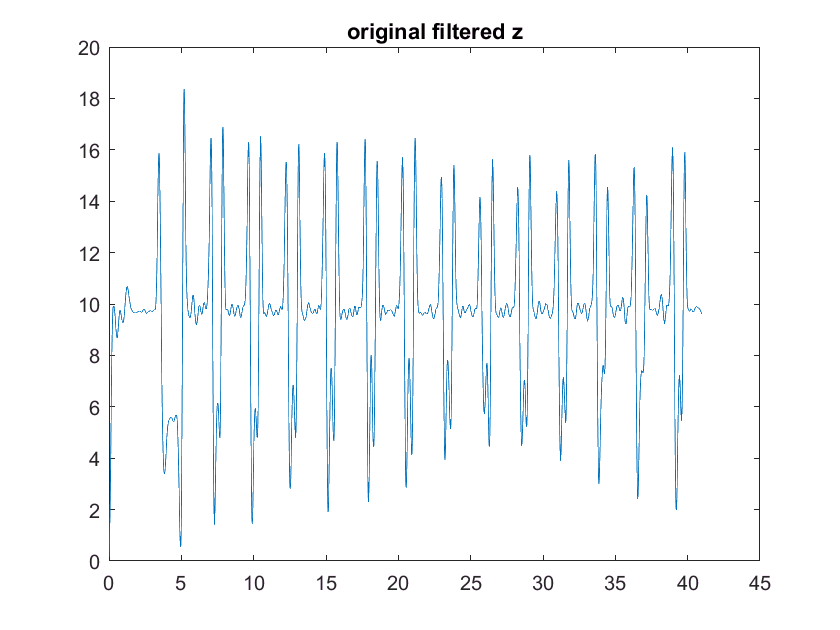

% visualize all data
plot(times,untouchedz)
title('original filtered z')

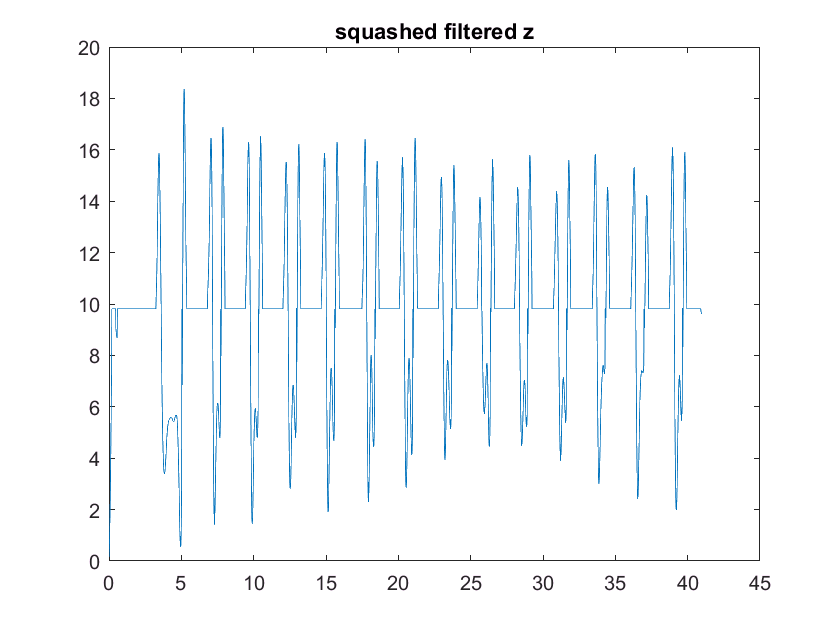

plot(times,zacc_squash)
title('squashed filtered z')

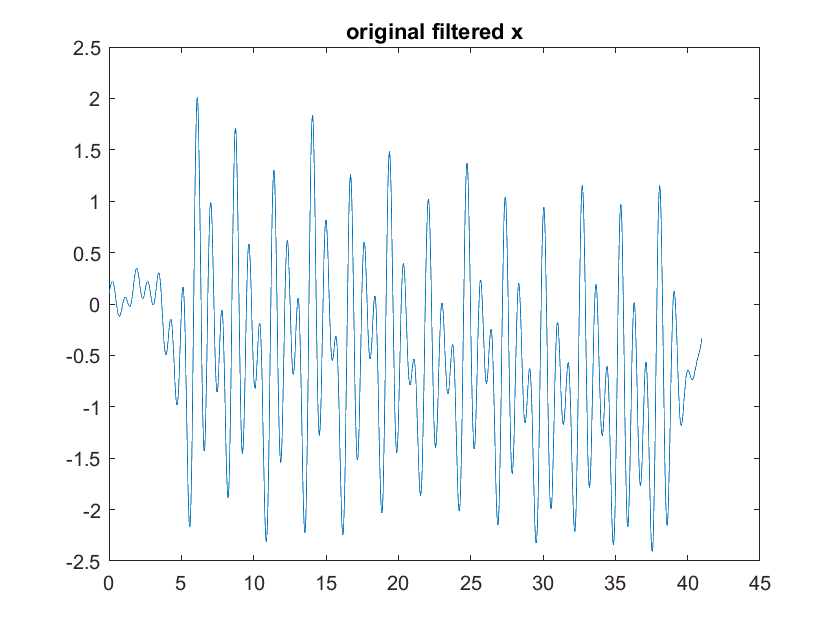

plot(times,x_ideal)
title('original filtered x')